# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá. SPAIN.**

# Topic 4 part 2: exercise 05 - **Find Corresponding Interest Points Between Pair of Images**

## Questions

## Questions,  Local Features

- Use the following detectors (step 2):  [`detectBRISKFeatures`](https://es.mathworks.com/help/vision/ref/detectbriskfeatures.html)`, `[`detectFASTFeatures`](https://es.mathworks.com/help/vision/ref/detectfastfeatures.html)

- In which of them are the greatest number of features detected?

- Scale the original image by a factor scale=0.7 using the `imresize` function. Then rotate it at an angle theta=30º, using the `imrotate` function, creating a distorted image.

- Apply the [`detectKAZEFeatures`](https://es.mathworks.com/help/vision/ref/detectkazefeatures.html) detector in section 2 to the distorted image.

- Find Matching Features Between the original and distorted Image from their descriptors, using `matchFeatures` function, after that retrieve locations of corresponding points for each image, usign indexes returned by the function. 

- Finally,  show the point matches usign `showMatchedFeatures` function.

Step 1) Read Image

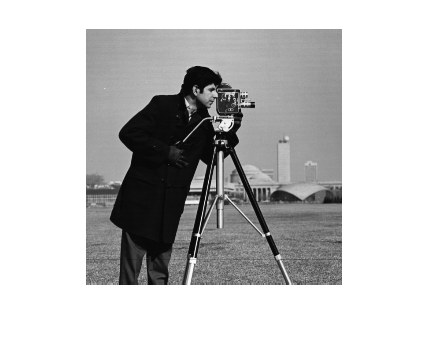

clear all
close all
% Read original image.
originalImage = imread('cameraman.tif');

title('Original image');
imshow(originalImage);

Step 2) Detect features in both images. 

originalPointsBRISK =  detectBRISKFeatures(originalImage,'MinContrast',0.01)

originalPointsBRISK =   1415×1 BRISKPoints array with properties:

          Scale: [1415×1 single]
    Orientation: [1415×1 single]
       Location: [1415×2 single]
         Metric: [1415×1 single]
          Count: 1415


originalPointsFAST = detectFASTFeatures(originalImage)

originalPointsFAST =   237×1 cornerPoints array with properties:

    Location: [237×2 single]
      Metric: [237×1 single]
       Count: 237


max(originalPointsBRISK.Count,originalPointsFAST.Count)

ans = 1415

El BRISK detecta más features

Step 3) Plot Features

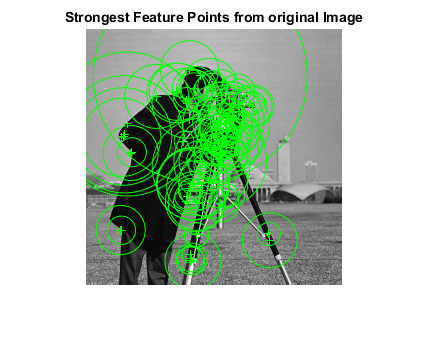

% strongest feature points
originalStrongest = originalPointsBRISK.selectStrongest(100);

figure; 
imshow(originalImage); 
title('Strongest Feature Points from original Image');
hold on;
plot(originalStrongest);

Step 4) Resize and Rotate the Image (distorted image), extract and find the features of both images

%En este apartado obtenemos las caracteríaticas de la fotografía original y
%la distorsionada
% Resize
scale = 0.7;
resizedImage=imresize(originalImage,scale);
%Rotate
theta = 30;
distorted=imrotate(resizedImage,theta);
pointsOrigionalBRISK  = detectBRISKFeatures(originalImage,'MinContrast',0.01);
pointsDistortedBRISK = detectBRISKFeatures(distorted,'MinContrast',0.01);

pointsOriginalFAST  = detectFASTFeatures(originalImage);
poinstDistortedFAST = detectFASTFeatures(distorted);

Step 5) Retrieve locations of corresponding points for each image.

%En este apartado extraemos los puntos válidos de abmas imágenes para posteriormente emparejarlos 

[featuresOriginalFREAK,validPtsOriginalBRISK]  = extractFeatures(originalImage,pointsOrigionalBRISK);
[featuresDistortedFREAK,validPtsDistortedBRISK] = extractFeatures(distorted,pointsDistortedBRISK);

[featuresOriginalFAST,validPtsOriginalFAST]  = extractFeatures(originalImage,pointsOriginalFAST);
[featuresDistortedFAST,validPtsDistortedFAST] = extractFeatures(distorted,poinstDistortedFAST);

%emparejamos con matchFeatures()
indexPairsBRISK = matchFeatures(featuresOriginalFREAK,featuresDistortedFREAK,'MatchThreshold',40,'MaxRatio',0.8);
matchedOriginalBRISK  = validPtsOriginalBRISK(indexPairsBRISK(:,1));
matchedDistortedBRISK = validPtsDistortedBRISK(indexPairsBRISK(:,2));

indexPairsFAST = matchFeatures(featuresOriginalFAST,featuresDistortedFAST);
matchedOriginalFAST  = validPtsOriginalFAST(indexPairsFAST(:,1));
matchedDistortedFAST = validPtsDistortedFAST(indexPairsFAST(:,2));

Step 6) Show putative point matches.

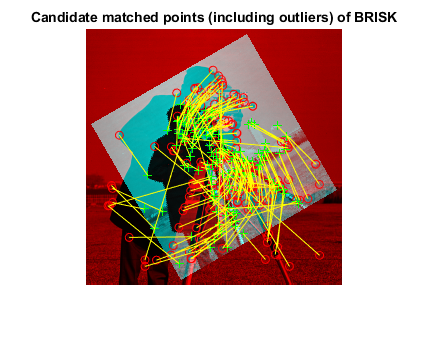

%En este apartado mostramos las dos imágenes y como quedan sus puntos emparejados, observamos que, gracias
%a las operaciones anteriores, hemos extraido y emparejado los puntos de
%las imágenes a pesar de la evidente distorsión de una de ellas.
% Display matched features. showMatchedFeatures function
figure
showMatchedFeatures(originalImage,distorted,matchedOriginalBRISK,matchedDistortedBRISK)
title('Candidate matched points (including outliers) of BRISK')

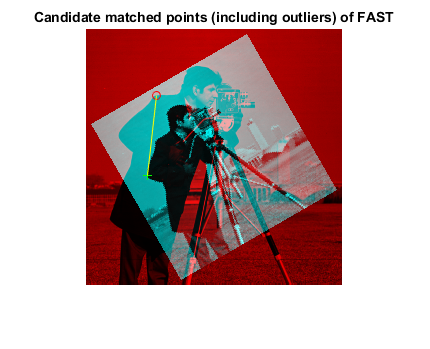


figure
showMatchedFeatures(originalImage,distorted,matchedOriginalFAST,matchedDistortedFAST)
title('Candidate matched points (including outliers) of FAST' )

Copyright 1993-2014 The MathWorks, Inc. 